# Assignment 03 - A.A. 2023/24

close all
clear
clc

## 0) Data

Loading data and plotting time histories

% Loading data
load('Data')
t=Data(:,1);
F=Data(:,2);
x=Data(:,3:end);    % displacements in the 4 columns
np=size(x,1);        % number of samples
nj=size(x,2);        % number of displacements

dt=t(2)-t(1);        % acquisition period
fsamp=1/dt;            % sampling frequency
disp(' ')

disp(['Number of sensors: ' num2str(nj)])

Number of sensors: 4


disp(['dt [s]: ' num2str(dt)])

dt [s]: 0.001


disp(['np [-]: ' num2str(np)])

np [-]: 60001


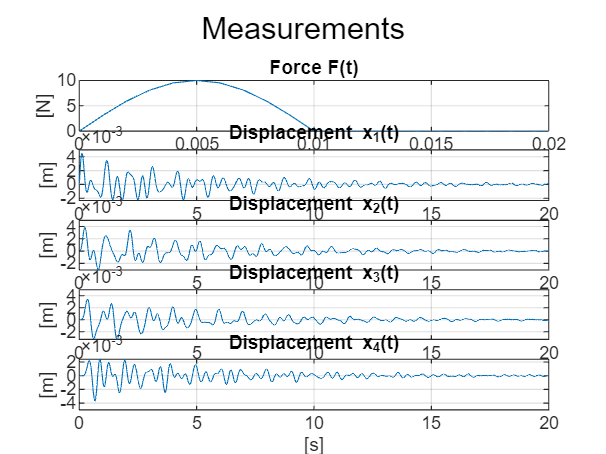


% Plots
figure()
sgtitle("Measurements");

subplot(5, 1, 1);
plot(t, F)
grid on;
title("Force F(t)");
ylabel("[N]");
xlabel("[s]");
xlim([0, 0.02]);

subplot(5, 1, 2);
plot(t, x(:, 1))
grid on;
title("Displacement x_1(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 3);
plot(t, x(:, 2))
grid on;
title("Displacement x_2(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 4);
plot(t, x(:, 3))
grid on;
title("Displacement x_3(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 5);
plot(t, x(:, 4))
grid on;
title("Displacement x_4(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

## 1) Experimental FRF

Plot the "experimental" FRF diagrams.

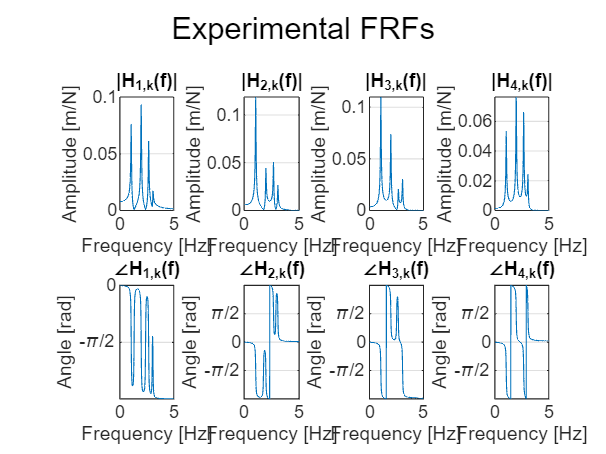

% Force and displacements spectra
[x_fft, frq] = ffg(x, np, dt);
[F_fft, frq] = ffg(F, np, dt);

% Experimental FRFs = ratio output/input
Hjk_exp = x_fft./F_fft;

% Plots
figure()
sgtitle("Experimental FRFs")
for i=1:nj
    % Plotting the amplitude
    subplot(2,4,i);
    plot(frq, abs(Hjk_exp(:, i)));
    grid on;
    title("|H_"+num2str(i)+"_,_k(f)|");
    ylabel("Amplitude [m/N]");
    xlabel("Frequency [Hz]");
    xlim([0, 5]);
    
    % Plotting the amplitude
    subplot(2,4,nj+i)
    plot(frq, angle(Hjk_exp(:, i)))
    grid on;
    title("\angleH_"+num2str(i)+"_,_k(f)");
    ylabel("Angle [rad]");
    xlabel("Frequency [Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    xlim([0, 5]);
end

## 2) Parameters estimation - simplified method

Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the range $0-5\;\textrm{Hz}$ employing simplified methods (e.g. half power point method). Comment the obtained results.

%{
fini = [0, 1.3, 2.4, 3];        % Lower f in band
ffin = [1.3, 2.4, 3, 5];        % Higher f in band

res = zeros(3,16);
resonance_freqs = zeros(16,1);
h = zeros(16,1); 
for jj = 1:4        % for each FRF
    for i = 1:4        % for each mode
        % Indexes indentification
        iini = min(find(round(frq*1000)/1000 >= fini(i)));
        ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
        disp('Frequency range')
        disp(['- fmin [Hz]: ' num2str(frq(iini))])
        disp(['- fmax [Hz]: ' num2str(frq(ifin))]) 
        
        % Count of points for identification
        npid = ifin - iini + 1;
        disp(['Number of points for the identification: ' num2str(npid)])
        
        % FRF evaluated in [fini, ffin]
        rfHjki = frq(iini:ifin);
        Hjkiexp = Hjk_exp(iini:ifin,:);
        
        % First guess of parameters: SIMPLIFIED METHODS
        
        % Natural frequency
        [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]

        f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
        w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
        
        % Adimensional damping ration (phase derivative)
        derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
        hii0 = -1/(w0i0*derFIjki);        % Guessing h
        r0i = 2*w0i0*hii0;        % c/m
        
        % Mode shapes
        Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
        % all the other constants are set equal to 0 (m_q = 1)
        
        resonance_freqs (i) = f0i;
        h(i) = hii0;


        % Results
        disp(' ')
        disp(['Initial guess f_0 [Hz]: ' num2str(f0i)])
        disp(['Initial guess h [-]:    ' num2str(hii0)])
        disp(['Initial guess A_0 [m]: ' num2str(Aj0)])
        

## 3) Residual minimization

Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.


        % Filling of vector xpar
        xpar0 = [hii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
        % for the initial guess of the optimization
        
        % Identification: single channel    
        options = optimset('fminsearch');
        options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
        xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);

        
        % @(xpar) parameter set we're trying to find
        % Error function (difference between experimental and optimized FRF)
        
        % Plot results of identification
        vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)]
        %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]

        disp("Modal parameters after minimization: mq"+num2str(i)+num2str(i)+ " = " +num2str(vpar(1))+ "; kq"+num2str(i)+num2str(i)+ " = " + num2str(vpar(2)) + "; cq" +num2str(i)+num2str(i)+ " = " + num2str(vpar(3)) );


        %Extracting the modal parameters
        % Each 4 consecutives columns of res contain the modal parameters
        % of the same mode of vibration but for a different measurement
        % point
        res(:, jj + 4*(i-1)) = vpar(1:3);
        
        Hjkiid = funHjki(vpar, rfHjki);
        %Reconstructing the experimental FRF after solving the minimization
        %problem
        %rfHjki the frequency range of interest
        
        figure()
        sgtitle(['H_' num2str(jj) '_k for mode ' num2str(i) ': Experimental vs Identified'])
        
        subplot(2, 1, 1);
        plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Magnitude");
        ylabel("[m/N]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
        
        subplot(2, 1, 2);
        plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Phase");
        ylabel("[°]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
    end
end
%}

## 2) + 3) Parameters Estimation & Residual minimization

2) Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the  range 0 − 5 𝐻𝐻𝐻𝐻 employing simplified methods (e.g. half power point method). Comment the  obtained results.  3) Set up a modal para

3) Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.

% FRF 1
fini = [0, 1.3, 2.4, 3];        % Lower f in band
ffin = [1.3, 2.4, 3, 5];        % Higher f in band
jj = 1;

[h1, res_freq1, mode_shape1, best_param1] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000338 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000023 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000008 



h1 =     0.0286
    0.0161
    0.0113
    0.0144


res_freq1 =     1.0500
    1.9666
    2.6666
    3.0833


mode_shape1 =     0.1891
    0.4335
    0.3852
    0.1209


best_param1 =     1.0000    1.0000    1.0000    1.0000
    0.3771    0.3161    0.3322    0.3331
   43.5235  154.1006  281.2161  371.9165
    0.1891    0.3795    0.3396    0.0958
         0   -0.0058    0.0011   -0.0136
         0    0.0021    0.0121    0.0017
         0   -0.0032    0.0015    0.0003
    0.0003    0.3138   -0.5576   -0.2882
         0   -0.1308   -4.1050   -2.5306


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000015 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000015 



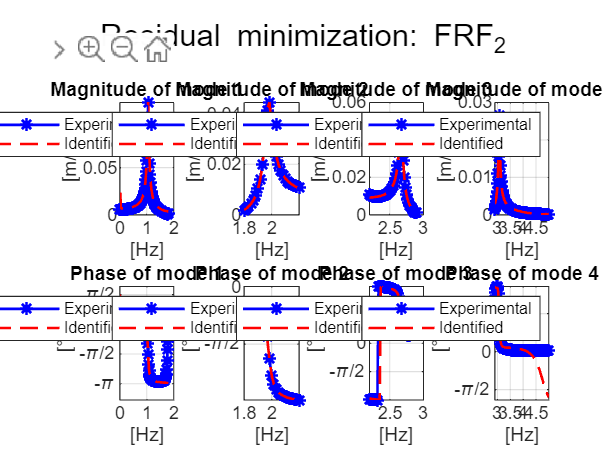

h2 =     0.0283
    0.0160
    0.0113
    0.0099


res_freq2 =     1.0500
    1.9833
    2.6666
    3.0666


mode_shape2 =     0.2928
    0.2031
   -0.3121
   -0.1943


best_param2 =     1.0000    1.0000    1.0000    1.0000
    0.3734    0.3325    0.3248    0.3130
   43.5235  154.0229  281.3743  371.4212
    0.2928    0.1841   -0.2685   -0.1569
         0    0.0013    0.0079    0.0061
         0   -0.0061   -0.0026   -0.0012
         0    0.0008    0.0034   -0.0007
    0.0003   -0.1241   -0.8363    0.4736
         0    0.0922   -0.6866    0.8548



% FRF 2
fini = [0, 1.8, 2.2, 2.9];        % Lower f in band
ffin = [1.8, 2.2, 2.9, 5];        % Higher f in band
jj = 2;

[h2, res_freq2, mode_shape2, best_param2] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000034 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000005 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000017 



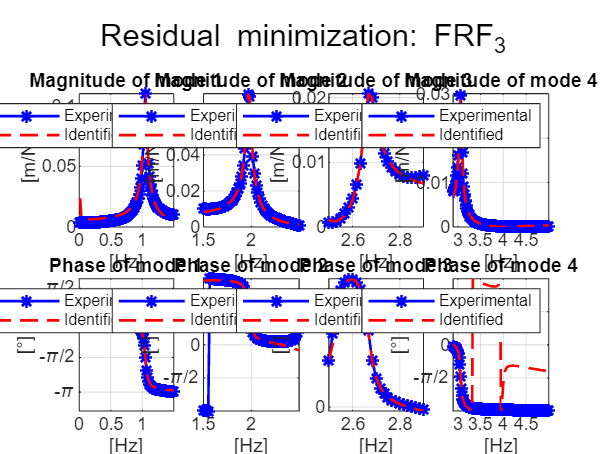

h3 =     0.0283
    0.0160
    0.0115
    0.0097


res_freq3 =     1.0500
    1.9666
    2.6666
    3.0666


mode_shape3 =     0.2704
   -0.3393
   -0.1325
    0.2123


best_param3 =     1.0000    1.0000    1.0000    1.0000
    0.3729    0.3378    0.3431    0.3527
   43.5235  154.0400  280.9101  370.9178
    0.2704   -0.3217   -0.1193    0.2033
         0   -0.0003   -0.0089    0.0087
         0   -0.0016    0.0054   -0.0001
         0   -0.0012   -0.0054   -0.0009
    0.0003    0.1492    1.4591    0.6180
         0   -0.1567   -0.3388    0.5771




% FRF 3
fini = [0, 1.5, 2.5, 2.9];        % Lower f in band
ffin = [1.5, 2.5, 2.9, 5];        % Higher f in band
jj = 3;

[h3, res_freq3, mode_shape3, best_param3] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: Inf 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000015 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000038 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000079 



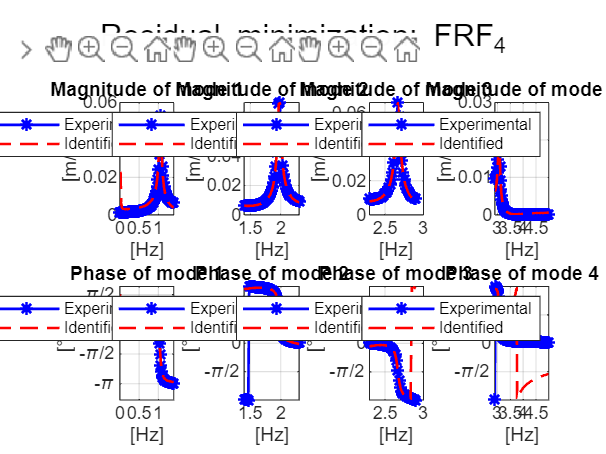

h4 =     0.0282
    0.0158
    0.0111
    0.0096


res_freq4 =     1.0500
    1.9833
    2.6666
    3.0666


mode_shape4 =     0.1308
   -0.3565
    0.4094
   -0.1736


best_param4 =     1.0000    1.0000    1.0000    1.0000
    0.3727    0.3391    0.3466    0.3356
   43.5235  153.9999  281.1403  370.4960
    0.1308   -0.3366    0.3872   -0.1589
         0   -0.0043    0.0081   -0.0185
         0    0.0047   -0.0061    0.0005
         0   -0.0020    0.0071   -0.0013
    0.0003    0.2141   -1.6958    0.6518
         0   -0.5034    1.7882   -0.8696




% FRF 4
fini = [0, 1.4, 2.3, 2.9];        % Lower f in band
ffin = [1.4, 2.3, 2.9, 5];        % Higher f in band
jj = 4;

[h4, res_freq4, mode_shape4, best_param4] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp)

% Comparing the different adimensional ratios
h_modes = zeros(4,4); %[-]
h_modes_mean = zeros(1,4);
h_modes_std = zeros(1,4);

res_freqs = zeros(4,4); %[Hz]
res_freqs_mean = zeros(1,4);
res_freqs_std = zeros(1,4);


mode_shapes = zeros(4,4); %[-]
mode_shapes_mean = zeros(1,4);
mode_shapes_std = zeros(1,4);

for i = 1:4 %For each mode
    h_modes(:,i)= [h1(i); h2(i); h3(i); h4(i)]; % Reorganizing parameters with respect to the node they are related to
    h_modes_mean(i) = mean(h_modes(:,i));       %computing the mean of h for each mode
    h_modes_std(i) = std(h_modes(:,i));         %computing the std of h for each mode

    res_freqs(:,i)= [res_freq1(i); res_freq2(i); res_freq3(i); res_freq4(i)]; % Reorganizing parameters with respect to the node they are related to
    res_freqs_mean(i) = mean(res_freqs(:,i));       %computing the mean of res_freq for each mode
    res_freqs_std(i) = std(res_freqs(:,i));         %computing the std of res_freq for each mode

    mode_shapes(:,i)= [mode_shape1(i); mode_shape2(i); mode_shape3(i); mode_shape4(i)]; % Reorganizing parameters with respect to the node they are related to
    mode_shapes_mean(i) = mean(mode_shapes(:,i));       %computing the mean of res_freq for each mode
    mode_shapes_std(i) = std(mode_shapes(:,i));         %computing the std of res_freq for each mode

end
h_modes_mean

h_modes_mean =     0.0283    0.0160    0.0113    0.0109


h_modes_std

h_modes_std =     0.0002    0.0002    0.0002    0.0023



res_freqs_mean

res_freqs_mean =     1.0500    1.9750    2.6666    3.0708


res_freqs_std

res_freqs_std =          0    0.0096         0    0.0083



mode_shapes_mean

mode_shapes_mean =     0.2208   -0.0148    0.0875   -0.0087


mode_shapes_std

mode_shapes_std =     0.0747    0.3960    0.3653    0.2060


mode_shape1 =     0.1891
    0.4335
    0.3852
    0.1209


mode_shape2 =     0.2928
    0.2031
   -0.3121
   -0.1943


mode_shape3 =     0.2704
   -0.3393
   -0.1325
    0.2123


mode_shape4 =     0.1308
   -0.3565
    0.4094
   -0.1736


## 4) Comparisons

Compare and comment the identified modal parameters with ones obtained with the above-mentioned methods.

%Using res my dawg
for j = 1:4        % for each FRF
    for i = 0:3
        disp(res(:, j+i*j))
    end
end

disp(res)

## 5) Modal approach - FRF reconstruction

Employing a modal approach, reconstruct the FRFs and compare with the “experimental” original ones.

% FRF 1
fini = [0, 1.3, 2.4, 3];        % Lower f in band
ffin = [1.3, 2.4, 3, 5];        % Higher f in band

jj = 1;
[h, res_freq, mode_shape, best_param] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp)




figure()
sgtitle("Residual minimization: FRF_" + num2str(jj));

for i = 1:4        % for each mode
    % Indexes indentification
    iini = min(find(round(frq*1000)/1000 >= fini(i)));
    ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
    
    % Count of points for identification
    npid = ifin - iini + 1;
    
    % FRF evaluated in [fini, ffin]
    rfHjki = frq(iini:ifin);
    Hjkiexp = Hjk_exp(iini:ifin,:);
    
    % Natural frequency
    [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]
    f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
    w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
    
    % Adimensional damping ration (phase derivative)
    derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
    hii0 = -1/(w0i0*derFIjki);        % Guessing h
    r0i = 2*w0i0*hii0;        % c/m
    
    % Mode shapes
    Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
    
    % Filling of vector xpar
    xpar0 = [hii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
    
    % Identification: single channel    
    options = optimset('fminsearch');
    options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
    xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);
    
    % @(xpar) parameter set we're trying to find
    % Error function (difference between experimental and optimized FRF)
    
    % Plot results of identification
    vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)];
    %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]
    
    %Reconstructing the experimental FRF after solving the minimization
    Hjkiid = funHjki(vpar, rfHjki);
    
    % Plots
    subplot(2, 4, i);
    plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Magnitude of mode " + num2str(i));
    ylabel("[m/N]");
    xlabel("[Hz]");
    legend("Experimental", "Identified");
    
    subplot(2, 4, i+4);
    plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Phase of mode " + num2str(i));
    ylabel("[°]");
    xlabel("[Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    legend("Experimental", "Identified");
end

% FRF 2
fini = [0, 1.8, 2.2, 2.9];        % Lower f in band
ffin = [1.8, 2.2, 2.9, 5];        % Higher f in band

jj = 2;
figure()
sgtitle("Residual minimization: FRF_" + num2str(jj));

for i = 1:4        % for each mode
    % Indexes indentification
    iini = min(find(round(frq*1000)/1000 >= fini(i)));
    ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
    
    % Count of points for identification
    npid = ifin - iini + 1;
    
    % FRF evaluated in [fini, ffin]
    rfHjki = frq(iini:ifin);
    Hjkiexp = Hjk_exp(iini:ifin,:);
    
    % Natural frequency
    [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]
    f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
    w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
    
    % Adimensional damping ration (phase derivative)
    derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
    hii0 = -1/(w0i0*derFIjki);        % Guessing h
    r0i = 2*w0i0*hii0;        % c/m
    
    % Mode shapes
    Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
    
    % Filling of vector xpar
    xpar0 = [hii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
    
    % Identification: single channel    
    options = optimset('fminsearch');
    options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
    xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);
    
    % @(xpar) parameter set we're trying to find
    % Error function (difference between experimental and optimized FRF)
    
    % Plot results of identification
    vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)];
    %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]
    
    %Reconstructing the experimental FRF after solving the minimization
    Hjkiid = funHjki(vpar, rfHjki);
    
    % Plots
    subplot(2, 4, i);
    plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Magnitude of mode " + num2str(i));
    ylabel("[m/N]");
    xlabel("[Hz]");
    legend("Experimental", "Identified");
    
    subplot(2, 4, i+4);
    plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Phase of mode " + num2str(i));
    ylabel("[°]");
    xlabel("[Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    legend("Experimental", "Identified");
end

% FRF 3
fini = [0, 1.5, 2.5, 2.9];        % Lower f in band
ffin = [1.5, 2.5, 2.9, 5];        % Higher f in band

jj = 3;





figure()
sgtitle("Residual minimization: FRF_" + num2str(jj));

for i = 1:4        % for each mode
    % Indexes indentification
    iini = min(find(round(frq*1000)/1000 >= fini(i)));
    ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
    
    % Count of points for identification
    npid = ifin - iini + 1;
    
    % FRF evaluated in [fini, ffin]
    rfHjki = frq(iini:ifin);
    Hjkiexp = Hjk_exp(iini:ifin,:);
    
    % Natural frequency
    [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]
    f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
    w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
    
    % Adimensional damping ration (phase derivative)
    derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
    hii0 = -1/(w0i0*derFIjki);        % Guessing h
    r0i = 2*w0i0*hii0;        % c/m
    
    % Mode shapes
    Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
    
    % Filling of vector xpar
    xpar0 = [hii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
    
    % Identification: single channel    
    options = optimset('fminsearch');
    options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
    xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);
    
    % @(xpar) parameter set we're trying to find
    % Error function (difference between experimental and optimized FRF)
    
    % Plot results of identification
    vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)];
    %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]
    
    %Reconstructing the experimental FRF after solving the minimization
    Hjkiid = funHjki(vpar, rfHjki);
    
    % Plots
    subplot(2, 4, i);
    plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Magnitude of mode " + num2str(i));
    ylabel("[m/N]");
    xlabel("[Hz]");
    legend("Experimental", "Identified");
    
    subplot(2, 4, i+4);
    plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Phase of mode " + num2str(i));
    ylabel("[°]");
    xlabel("[Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    legend("Experimental", "Identified");
end

% FRF 4
fini = [0, 1.4, 2.3, 2.9];        % Lower f in band
ffin = [1.4, 2.3, 2.9, 5];        % Higher f in band

jj = 4;
figure()
sgtitle("Residual minimization: FRF_" + num2str(jj));

for i = 1:4        % for each mode
    % Indexes indentification
    iini = min(find(round(frq*1000)/1000 >= fini(i)));
    ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
    
    % Count of points for identification
    npid = ifin - iini + 1;
    
    % FRF evaluated in [fini, ffin]
    rfHjki = frq(iini:ifin);
    Hjkiexp = Hjk_exp(iini:ifin,:);
    
    % Natural frequency
    [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]
    f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
    w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
    
    % Adimensional damping ration (phase derivative)
    derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
    hii0 = -1/(w0i0*derFIjki);        % Guessing h
    r0i = 2*w0i0*hii0;        % c/m
    
    % Mode shapes
    Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
    
    % Filling of vector xpar
    xpar0 = [hii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
    
    % Identification: single channel    
    options = optimset('fminsearch');
    options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
    xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);
    
    % @(xpar) parameter set we're trying to find
    % Error function (difference between experimental and optimized FRF)
    
    % Plot results of identification
    vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)];
    %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]
    
    %Reconstructing the experimental FRF after solving the minimization
    Hjkiid = funHjki(vpar, rfHjki);
    
    % Plots
    subplot(2, 4, i);
    plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Magnitude of mode " + num2str(i));
    ylabel("[m/N]");
    xlabel("[Hz]");
    legend("Experimental", "Identified");
    
    subplot(2, 4, i+4);
    plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
    grid on;
    title("Phase of mode " + num2str(i));
    ylabel("[°]");
    xlabel("[Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    legend("Experimental", "Identified");
end